# Cell Complex

A cell complex provides a combinatorial representation of a space composed of nodes (0-cells), edges connecting pairs of nodes (1-cells), and faces (2-cells) bounded by closed loops of edges. In a two-dimensional grid, each face is typically a square formed by four edges. This representation explicitly encodes local topological structure and higher-order relationships beyond simple pairwise node-to-node connectivity. Such a data structure is not natively supported in MATLAB or any other programming language. We therefore first construct a cell complex data structure that explicitly represents nodes, edges, and faces. 

(C) 2026 Moo K. Chung, University of Wisconsin–Madison

Update history: 2026 Mar 9

#### Generating Cell Complex on Grid

clear all; close all; clc;
S = cellcomplex_build(4, 4)  %Generate 4 by 4 cell complex

S = struct with fields:
    nodes: [25×2 double]
    edges: [40×2 double]
    faces: [1×1 struct]


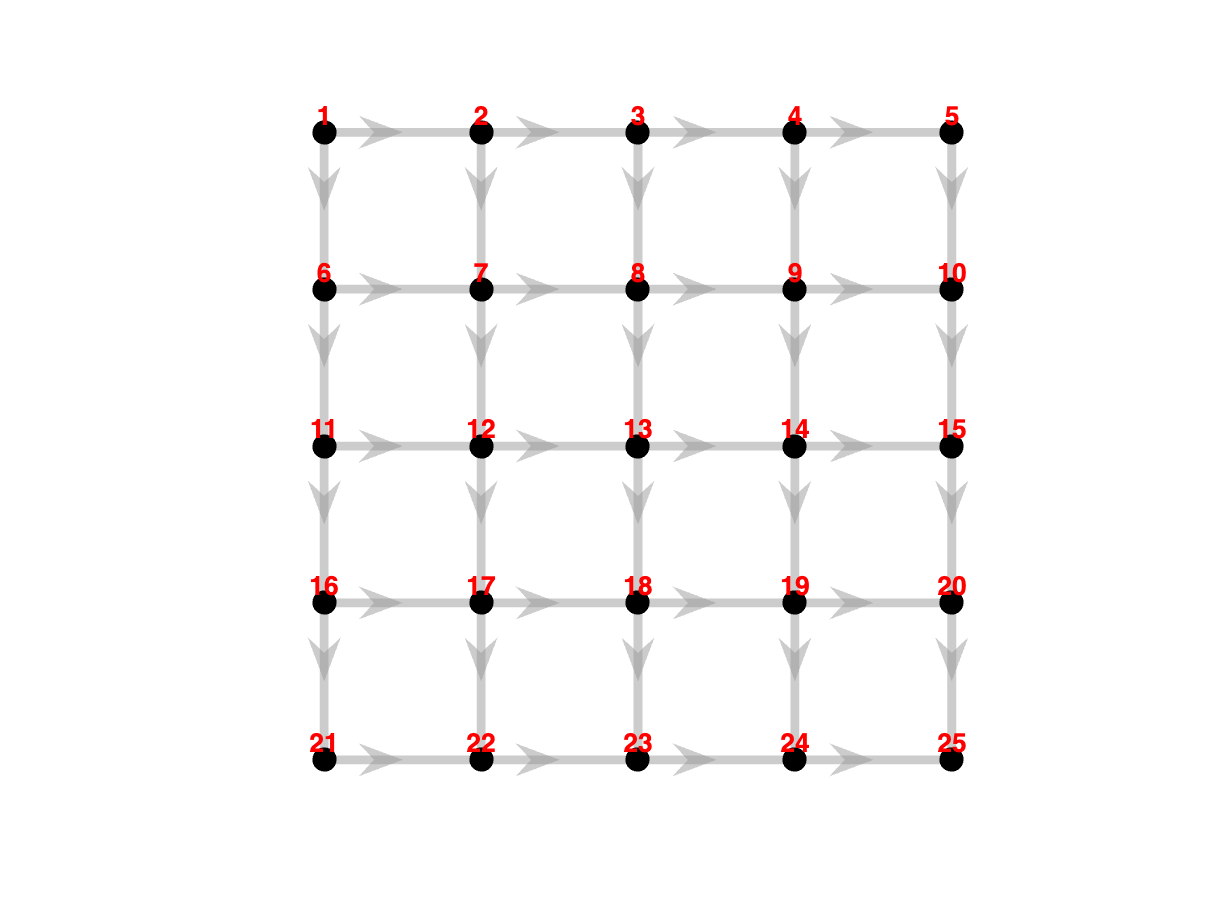

figure; cellcomplex_display(S);    %Display cell complex
cellcomplex_annotate_nodes(S, 'r') %Anotate nodes with red color

Structure **S** represents a two-dimensional cell complex. S.nodes is a 25 × 2 matrix containing the coordinates of the vertices (0-cells). Each row stores the spatial location of a node as [x_i  y_i] so node i is located at position (x_i, y_i). In this example there are 25 nodes, which typically correspond to a 5 × 5 grid of points. **S.edges** is a 40 × 2 matrix describing the *directed* edges (1-cells). By default, for each pair of adjacent nodes the edge direction is assigned from the node with the smaller index to the node with the larger index. As a result, horizontal edges are oriented from left to right because the node on the left is indexed earlier than the node on the right. Similarly, vertical edges are oriented from top to bottom because the nodes are numbered row by row starting from the top row and proceeding downward.

S.faces

ans = struct with fields:
    vertices: [16×4 double]
       edges: [16×4 double]
        sign: [16×1 double]


**S.faces** is a structure describing the two-dimensional cells (faces). The variable S.faces stores the two-dimensional cells (faces) of the cell complex. Each row of the matrix **S.faces.vertices** contains the vertex indices that form the boundary of one face. Because the complex is built on a grid, each face is a square and therefore has four vertices. Thus the matrix size [16 × 4] indicates that the complex currently contains 16 square faces. The matrix **S.faces.edges** lists the edges forming the boundary of eace face. Each row corresponds to one face and contains the indices of the four edges that form the closed boundary loop around that square. 

The vector **S.faces.sign** stores the orientation of each face. In general, a face orientation is represented by the value **+1** for clockwise orientation and **−1** for counter-clockwise orientation. This value indicates the direction in which the boundary edges circulate around the face. When the value is **0**, it means that no orientation has been assigned yet, so the face exists geometrically but its boundary direction has not been specified.

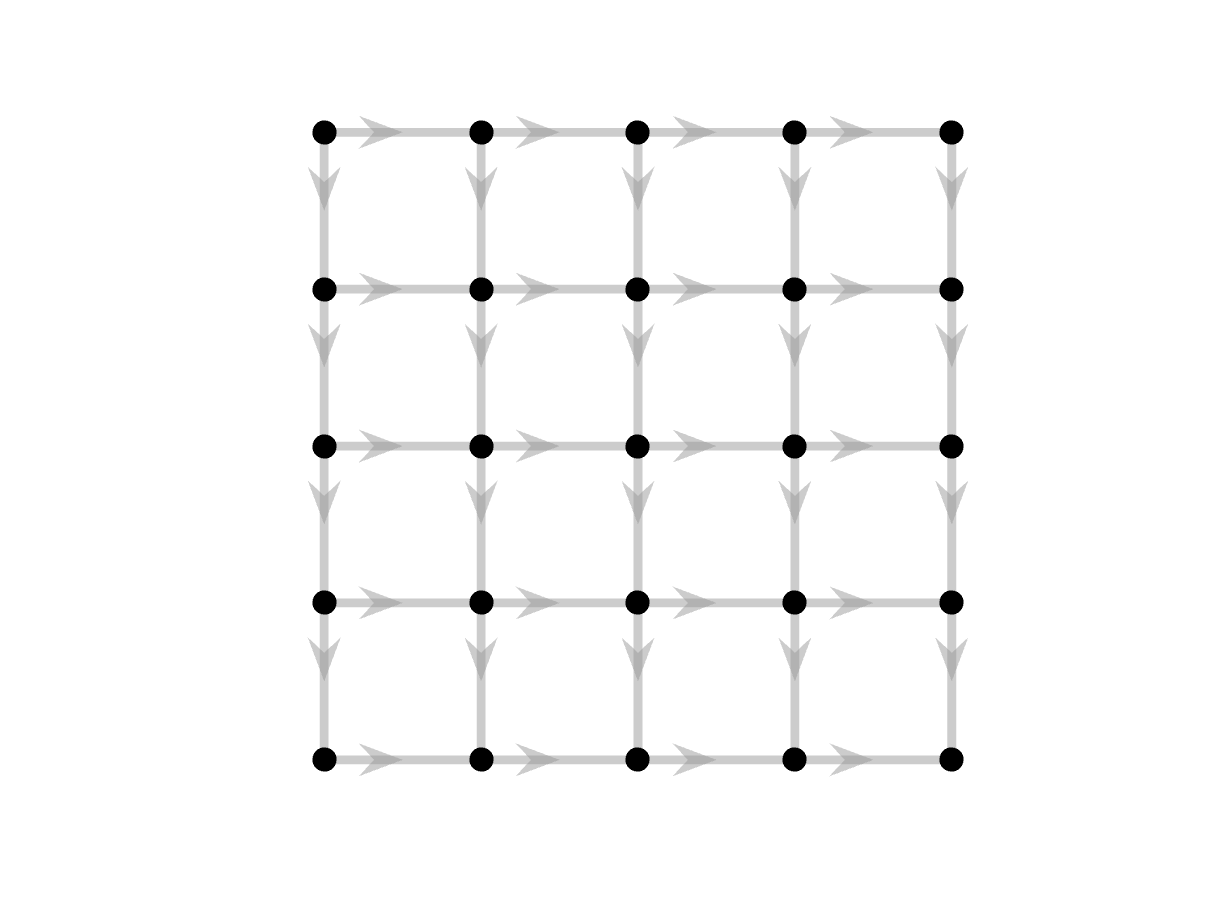

figure; cellcomplex_display(S);

#### Random two-cells 

The baseline cell complex built with **cellcomplex_build** does not represent each square as an oriented cycle because the default edge directions are assigned independently according to node ordering and are therefore not necessarily consistent around a face. To construct coherent 2-cells, we first randomly select square faces on the grid. Each square face is selected independently with probability p, following a Bernoulli distribution, i.e., $Bernoulli(p)$, producing a random subset of faces. Neighboring squares that share an edge are then merged into the same connected region. Edges shared by two selected faces are removed because they lie in the interior of the merged region and do not belong to its boundary. These boundary edges are arranged so that the end of one edge connects to the start of the next, producing a closed cycle around the region. Each boundary cycle is assigned a consistent orientation. The direction of the cycle is chosen randomly, with probability 1/2 for clockwise orientation and probability 1/2 for counterclockwise orientation. As a result, each connected region forms a coherent directed cycle representing the boundary of a merged two-dimensional face shown below. 

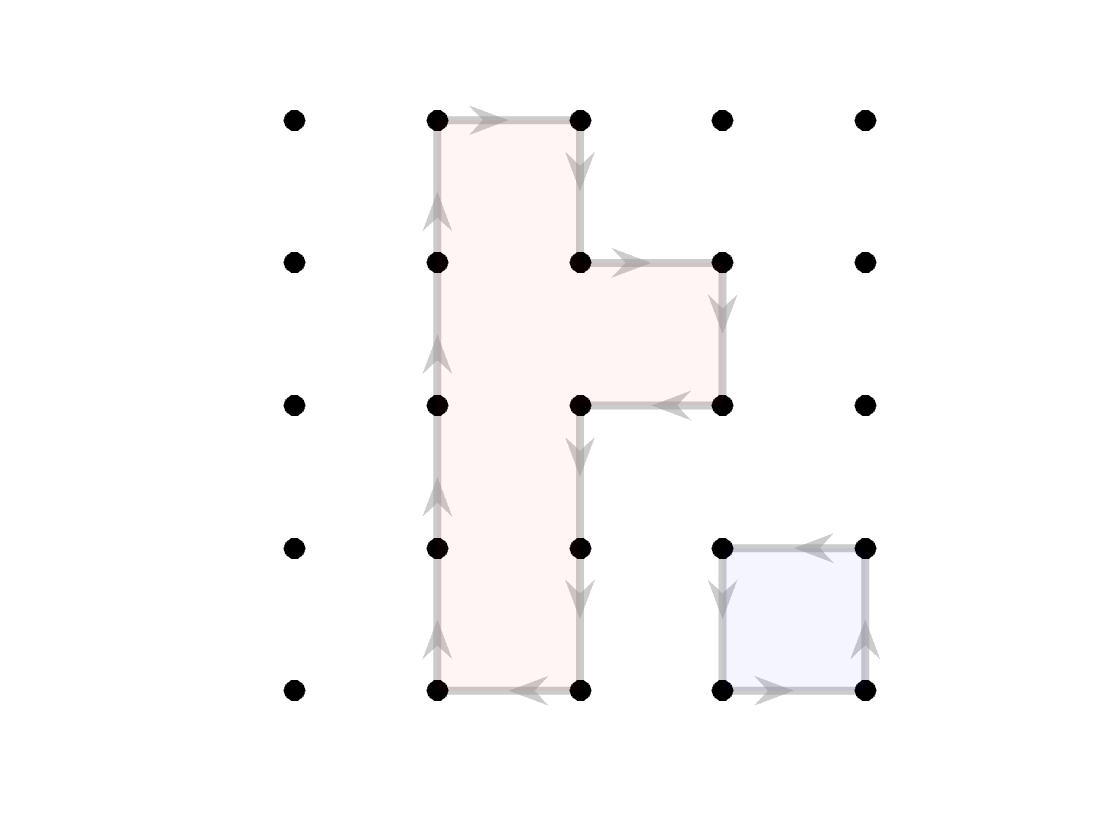

S = cellcomplex_add_faces_random(S, 0.5,8);
figure; cellcomplex_display(S); 

#### Dynamically Changing Cell Complex 

To illustrate how the topology of the cell complex change over time, we generate a sequence of random cell complexes by repeatedly sampling faces using the Bernoulli face model described above. At each time step, square faces on the grid are selected independently with probability p. Neighboring selected faces merge into connected regions, interior edges are removed, and the outer boundaries are reconstructed as directed cycles.

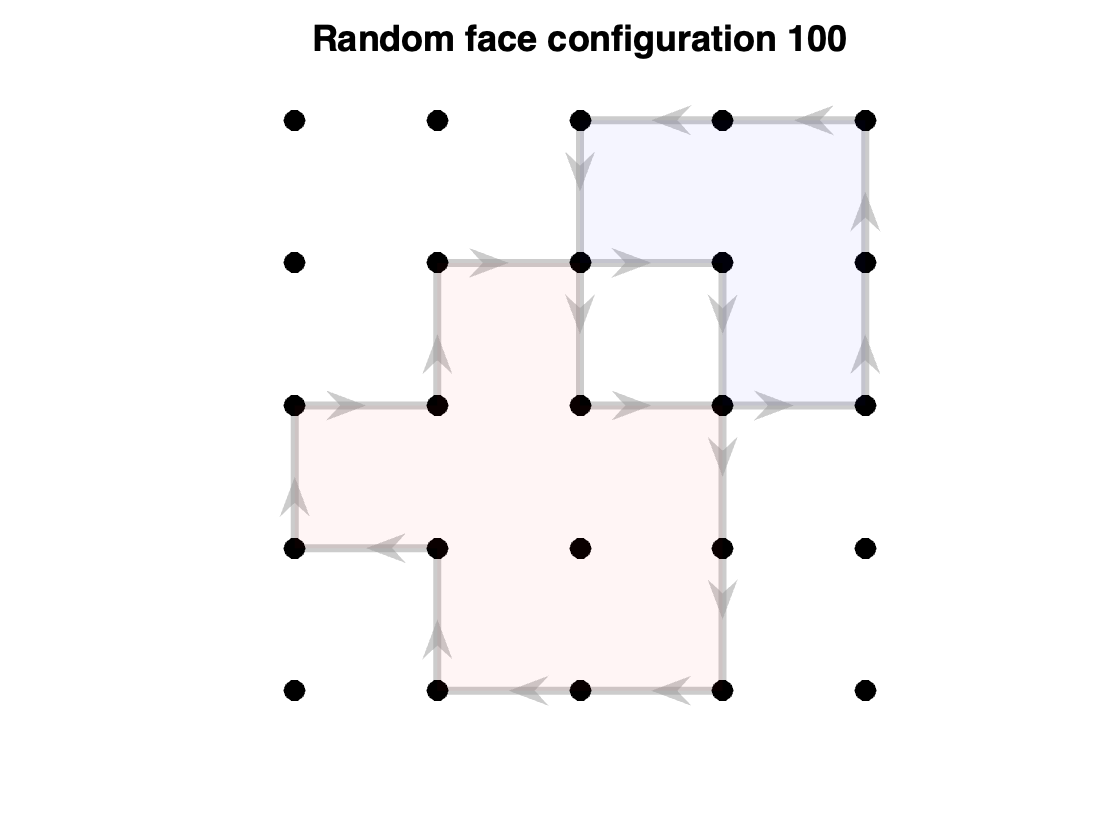

% Animate random fluctuations of faces

nFrames = 100;                 % number of animation steps
pauseTime = 0.5;             % speed of animation

%figure;
for k = 1:nFrames
   
    S2 = cellcomplex_add_faces_random(S, 0.5, randi(1e6));   % random seed each frame
    clf;
    cellcomplex_display(S2);
    title(sprintf('Random face configuration %d', k),'FontSize',18);
    drawnow;
  
    pause(pauseTime);
    
end

#### Problems

Based on the Bernoulli model $Bernoulli(p)$ for generating random cell complexes, which may be viewed as a simplified model for biological cell growth, consider the following problems.

- Suppose each face on an $m \times n$ grid $\mathbb{Z}_{m,n}$ is selected independently with probability p. Derive the expected number of selected faces. Prove the statement if possible and numeircally demonstate. 

- Let $N_n(p)$denote the number of connected face regions in $\mathbb{Z}_{n,n}$ when each face is selected independently with probability p. For fixed $p \in (0,1)$, investigate the asymptoic behavior of $N_n(p)/n^2$as n goes to $\infty$. Prove the statement if possible and numeircally demonstate.

- Let $C_n(p)$ denote the number of boundary cycles in an $\mathbb{Z}_{n,n}$. Investigate the asymptoic behavior of behavior of $C_n(p)/n^2$ as n goes to $\infty$. Prove the statement if possible and numeircally demonstate.